# **RS-EO-07-01: Routing Simulation**

**UT Austin Aerospace Engineering**

**Hongseok Kim**

**12/18/2024**

## I. Load Constellation

clear;
addpath('~/Desktop/Redstone_Project/RS_EO/RS_EO_01_Constellation_Initialization/');
addpath('~/Desktop/Redstone_Project/RS_EO/RS_EO_02_Constant_Area_Capture/');
addpath('~/Desktop/Redstone_Project/RS_HL/RS_HL_01_Constellation_Scinario_Formulation/')
addpath('~/Desktop/Redstone_Project/RS_EO/RS_EO_07_Constellation_Simulation/')
addpath('~/Desktop/Redstone_Project/RS_EO/RS_EO_05_Satellite_Network_Design/')
addpath('~/Desktop/Redstone_Project/RS_EO/RS_EO_06_MDP_Structure_Design/')
load('state_transition_matrix.mat');
load('state_reward_matrix.mat');
load('constellation_setting.mat')

## II. Add Target Ground Point, Add Contact Sequence

ground_target = ["Austin", 30.2672, -97.7431, 15;
               "New York", 40.7128, -74.0060, 10;
               "Los Angeles", 34.0522, -118.4837, 71;
               "Chicago", 41.8781, -87.6298, 181;
               "Houston", 29.7604, -95.3698, 30;
               "Phoenix", 33.4484, -112.0740, 331;
               "Philadelphia", 39.9526, -75.1652, 12;
               "San Antonio", 29.4481, -98.4936, 198;
               "San Diego", 32.7157, -117.1611, 22;
               "Dallas", 32.7767, -96.7970, 137;
               "London", 51.5074, -0.1278, 35;
               "Tokyo", 35.6895, 139.6917, 6;
               "Paris", 48.8566, 2.3522, 35;
               "Moscow", 55.7558, 37.6176, 155;
               "Sydney", -33.8688, 151.2093, 19;
               "Toronto", 43.6511, -79.3830, 76;
               "Berlin", 52.5200, 13.4050, 34;
               "Rome", 41.9028, 12.4964, 17;
               "Seoul", 37.5665, 126.9780, 23;
               "Mumbai", 19.0760, 72.8777, 14;
               "Beijing", 39.9042, 116.4074, 43;
               "Mexico City", 19.4326, -99.1332, 2240;
               "São Paulo", -23.5505, -46.6333, 780;
               "Bangkok", 13.7563, 100.5018, 2;
               "Istanbul", 41.0082, 28.9784, 39;
               "Cairo", 30.0444, 31.2357, 23;
               "Dubai", 25.2769, 55.2963, 4;
               "Singapore", 1.3521, 103.8198, 15;
               "Hong Kong", 22.3193, 114.1694, 39;
               "Sydney", -33.8688, 151.2093, 19];


elevation_angle_condition = 45;


gs = groundStation(scenario,"Name",ground_target(:,1), ...
                        "Latitude",str2double(ground_target(:,2)), ...
                        "Longitude", str2double(ground_target(:,3)), ...
                        "Altitude", str2double(ground_target(:,4)), ...
                        "MinElevationAngle", elevation_angle_condition ...
                        );

## III. Collect Data Generatin Points

[time_vector, ...
 sat_to_gs_access_table, ...
 sat_to_gs_access_matrix, ...
 sat_data_generation_matrix, ...
 sat_to_gs_access_info] = sat_to_gs_access_info_generation(scenario,scenario.Satellites,gs);

[start_state_vector, start_time_vector] = find(sat_data_generation_matrix == 1)


## IV. Proceed MDP Policy Iteration Algorithm

time_index_vector = 1:length(time_vector)-1;


%% Configure MDP Structure (Level 1 - 6)
MDP = config_MDP_struct(state_transition_matrix,state_reward_matrix, time_index_vector);

%% Policy Iteration Process for Last Timestep
number_of_states = length(state_transition_matrix(1,:,1));

pi_distribution = zeros(number_of_states);
policy_iteration_count = 1;
gamma = 1;

while true

    MDP = policy_evaluation_process(MDP, time_index_vector,state_transition_matrix, policy_iteration_count,gamma);

   [MDP,pi_distribution_updated] = policy_improvement_process(MDP,time_index_vector, state_transition_matrix);

   if pi_distribution == pi_distribution_updated
       break;
   end

   pi_distribution = pi_distribution_updated;
   policy_iteration_count = policy_iteration_count +1;

end

MDP.(['time' num2str(max(time_index_vector))]).policy_distribution = pi_distribution;

%% State and Action value propagation to t_n-1 ... t_1
MDP = value_function_propagation(MDP,time_index_vector,state_transition_matrix, gamma);

## III. State Value Change Over Time

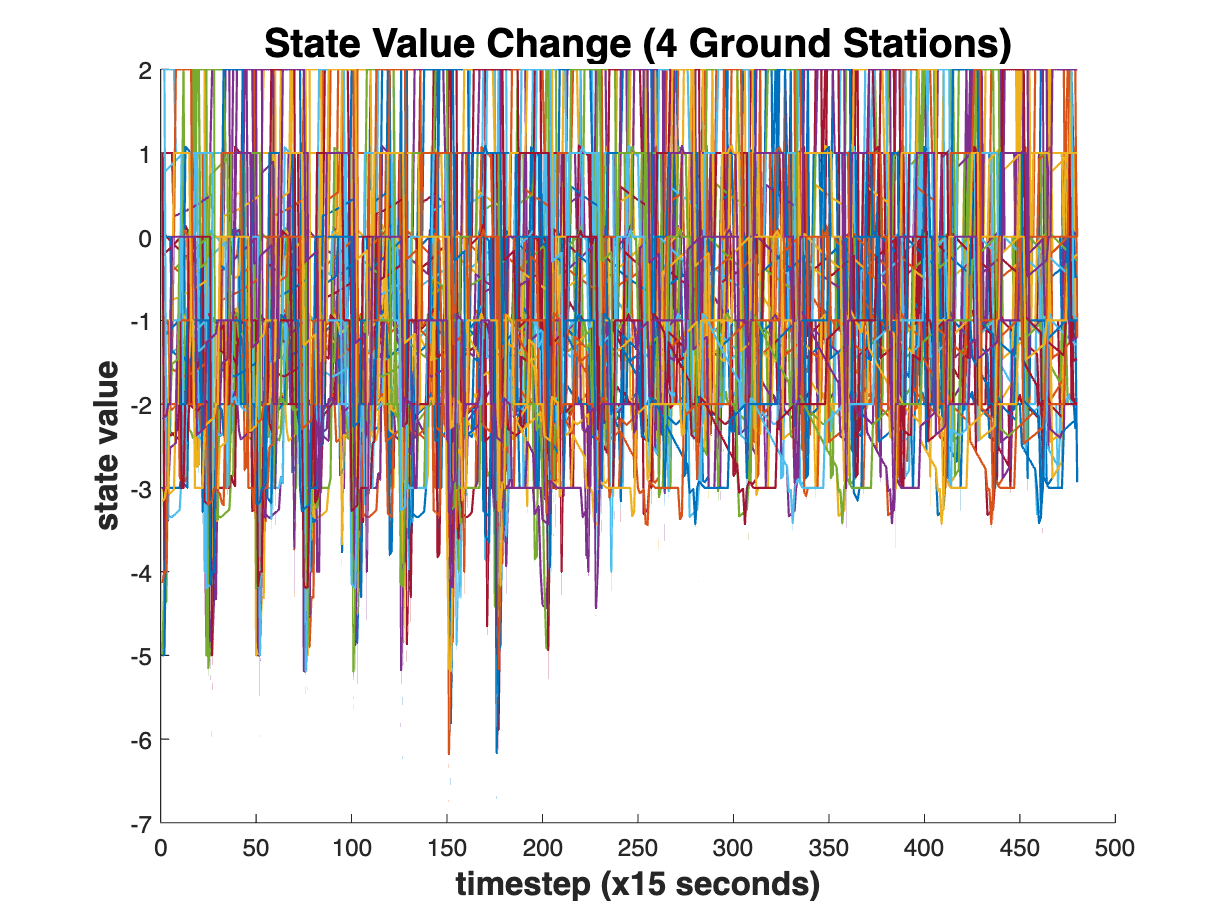

state_vector = 1:60;

state_change_value_matrix = zeros(length(time_index_vector),length(state_vector));

for time_index = time_index_vector
    for state_index = state_vector
        state_value_number = MDP.(['time' num2str(time_index)]).(['state' num2str(state_index)]).('state_value');
        state_change_value_matrix(time_index-min(time_index_vector)+1,state_index) = state_value_number;
    end
end
figure;
hold on
for state_index = state_vector
   plot(time_index_vector,state_change_value_matrix(:,state_index),'LineWidth',1)
end
hold off
title('State Value Change (4 Ground Stations)','FontSize',18,'FontWeight','bold')
xlabel('timestep (x15 seconds)','FontSize',15,'FontWeight','bold')
ylabel('state value','FontSize',15,'FontWeight','bold')

## IV. Propate the States from given start time and start state

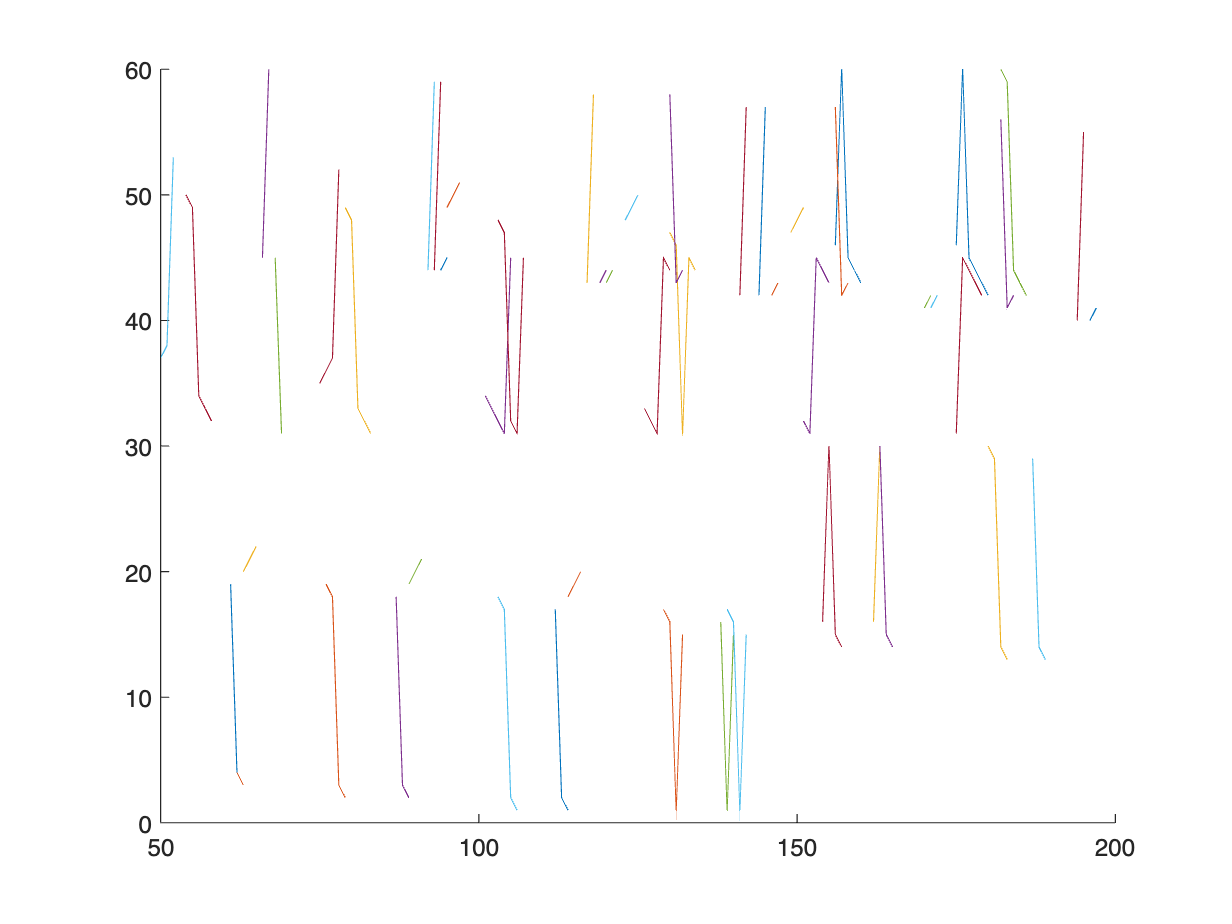

arrival_state = 61:72;

state_matrix = zeros(length(time_index_vector), length(start_state_vector));
reward_matrix = zeros(length(time_index_vector), length(start_state_vector));
cumulative_reward_matrix = zeros(length(time_index_vector), length(start_state_vector));
state_value_matrix = zeros(length(time_index_vector), length(start_state_vector));

% Result Display
length_of_routing_path_vector = zeros(length(start_state_vector),1);
state_value_vector_for_starting_state = zeros(length(start_state_vector),1);

figure;
hold on

for start_state_index = 1:length(start_state_vector)

  start_state = start_state_vector(start_state_index);
  start_time = start_time_vector(start_state_index);
  

  if start_time > length(time_vector) - 5
  continue;
  end

  [time_list, state_list, reward_list, cumulative_reward_list, state_value_list] = simulation_test(start_time,start_state,MDP,time_index_vector, arrival_state);
  A =  [time_list, state_list, reward_list];

  for time_index = 1:length(time_list)
    state_matrix(time_list(time_index), start_state) = state_list(time_index);
  end
  
  plot(time_list(1:end-1), state_list(1:end-1))

  t_0 = time_list(1);
  reward_matrix(t_0:t_0+length(reward_list)-1, start_state) = reward_list;
  cumulative_reward_matrix(t_0:t_0+length(cumulative_reward_list)-1, start_state) = cumulative_reward_list;
  state_value_matrix(t_0:t_0+length(state_value_list)-1, start_state) = state_value_list;

 length_of_routing_path_vector(start_state_index) = length(state_list) - 1;
 state_value_vector_for_starting_state(start_state_index) = state_change_value_matrix(start_time, start_state);
end

hold off
xlim([50,200])

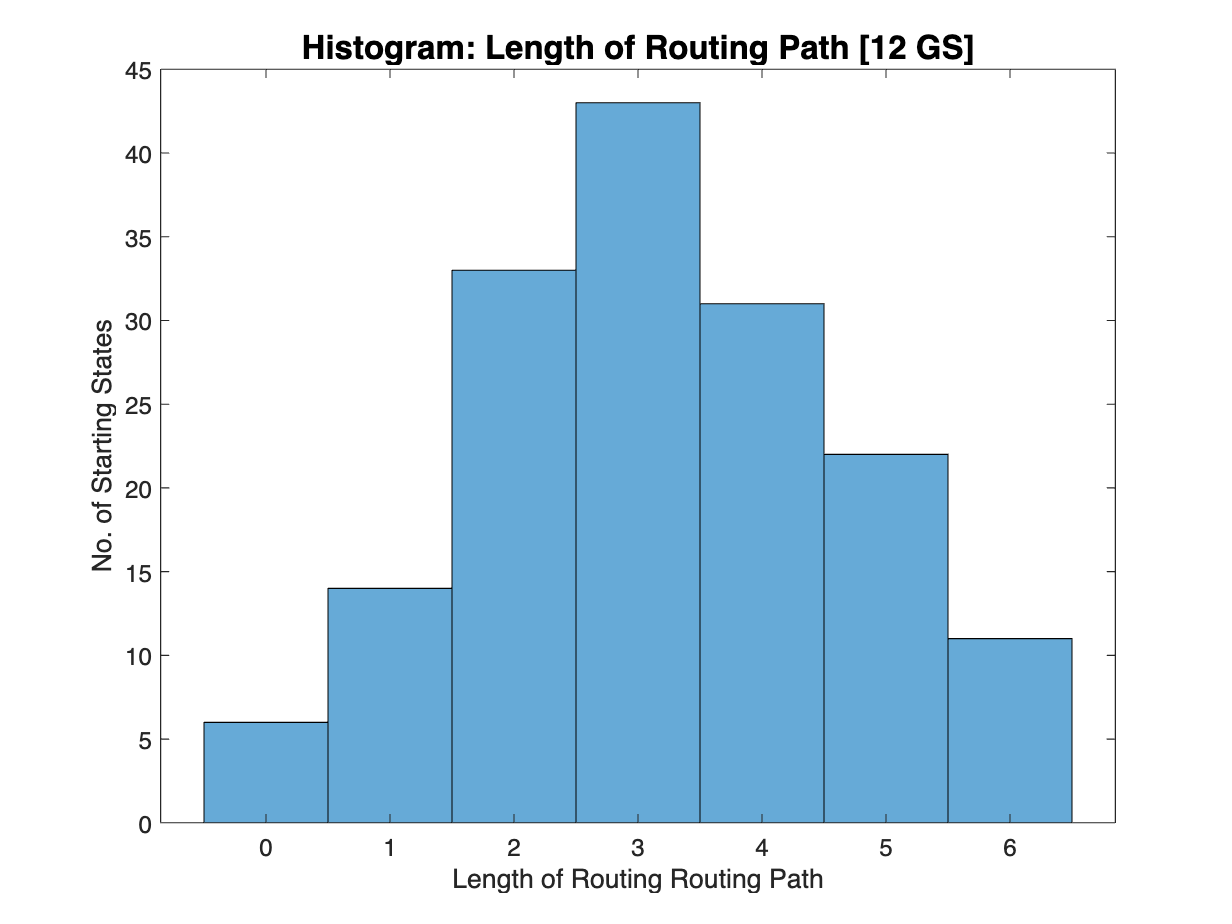



histogram(length_of_routing_path_vector)
title('Histogram: Length of Routing Path [12 GS]','FontSize',15,'FontWeight','bold')
xlabel('Length of Routing Routing Path')
ylabel('No. of Starting States')

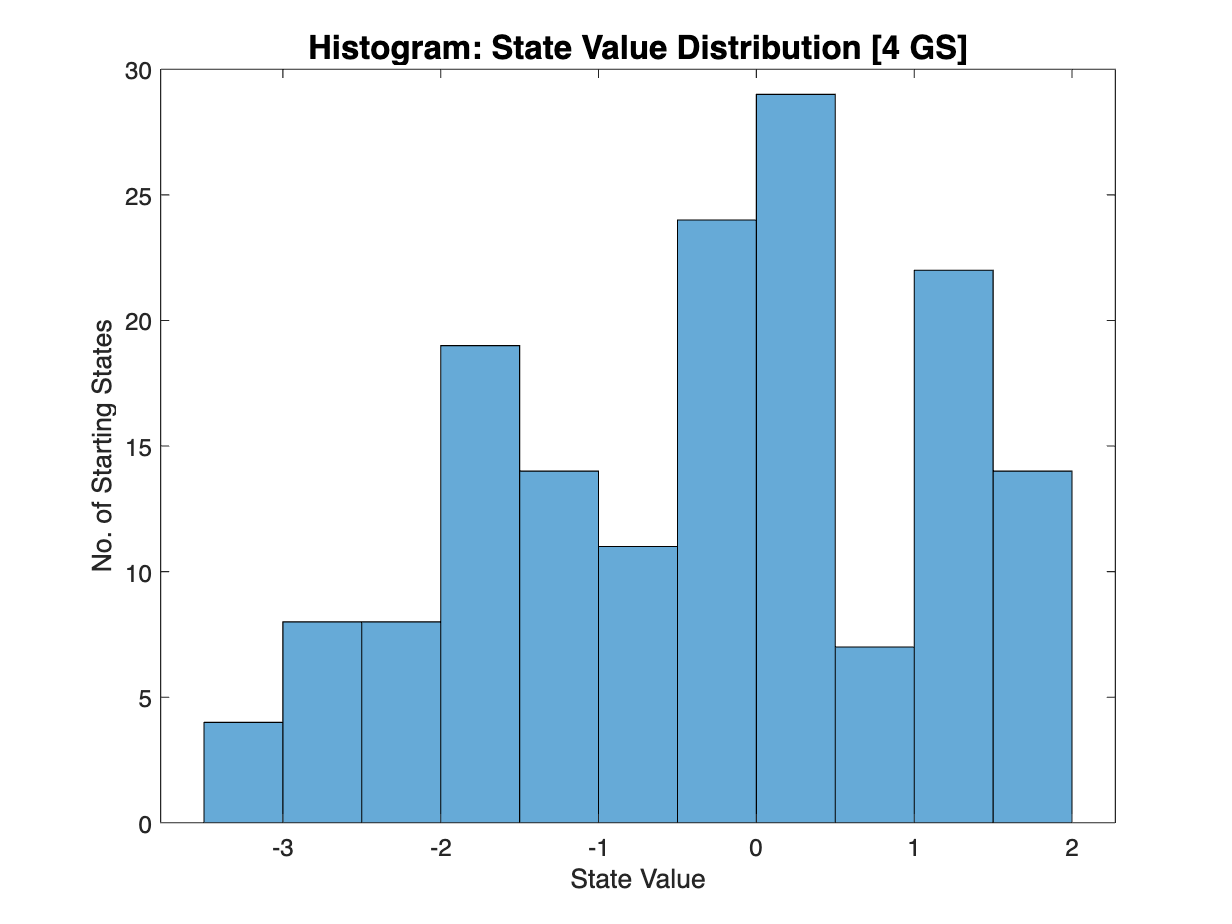




histogram(state_value_vector_for_starting_state,'BinWidth',0.5)
title('Histogram: State Value Distribution [4 GS]','FontSize',15,'FontWeight','bold')
xlabel('State Value')
ylabel('No. of Starting States')



mean_state_value = mean(state_value_vector_for_starting_state)

mean_state_value = -0.4296

std_state_value = std(state_value_vector_for_starting_state)

std_state_value = 1.3886

mean_length = mean(length_of_routing_path_vector)

mean_length = 3.1812

std_length = std(length_of_routing_path_vector)

std_length = 1.4958